# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 29-Apr-2024 16:33:58

## Create Array of Layers

layers = [
    imageInputLayer([128 128 3],"Name","imageinput")
    scalingLayer("Name","scaling")
    convolution2dLayer([3 3],8,"Name","conv","Padding","same")
    batchNormalizationLayer("Name","batchnorm")
    reluLayer("Name","relu")
    maxPooling2dLayer([5 5],"Name","maxpool","Padding","same")
    convolution2dLayer([3 3],16,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([5 5],"Name","maxpool_1","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([5 5],"Name","maxpool_2","Padding","same")
    convolution2dLayer([3 3],64,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    maxPooling2dLayer([5 5],"Name","maxpool_3","Padding","same")
    convolution2dLayer([3 3],64,"Name","conv_4","Padding","same")
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")
    maxPooling2dLayer([5 5],"Name","maxpool_4","Padding","same")
    convolution2dLayer([3 3],128,"Name","conv_5","Padding","same")
    batchNormalizationLayer("Name","batchnorm_5")
    reluLayer("Name","relu_5")
    maxPooling2dLayer([5 5],"Name","maxpool_5","Padding","same")
    convolution2dLayer([3 3],128,"Name","conv_6","Padding","same")
    batchNormalizationLayer("Name","batchnorm_6")
    reluLayer("Name","relu_6")
    maxPooling2dLayer([5 5],"Name","maxpool_6","Padding","same")
    globalAveragePooling2dLayer("Name","gapool")
    fullyConnectedLayer(64,"Name","fc")
    reluLayer("Name","relu_7")
    dropoutLayer(0.2,"Name","dropout")
    fullyConnectedLayer(8,"Name","fc_1")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Plot Layers

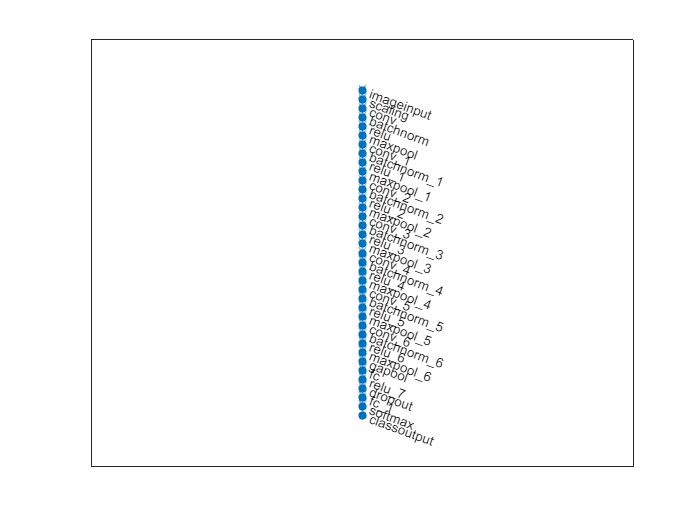

plot(layerGraph(layers));